### This script generates a complex desired attack image that statistically matches the background clutter of a real SAR input image. This is an adversarial technique used for validating the performance of target detection systems against spoofing.

clc; clear; close all; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sar_algo = 'LIA';   % Options: 'BPA' 'LIA'

% Detection / CFAR-like Parameters
Pfa_db    = -60;    % Desired Probability of False Alarm in dB (unused in new mask, kept for reference)
GuardCells = 5;    % Size of buffer around detected target (pixels)


% Object mask thresholds in dB
core_pct  = 99;     % percentile for very bright cores
halo_pct  = 95;     % percentile for softer halo expansion
min_area  = 10;     % minimum connected area (pixels) to keep as a "real" object
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

% --- 1. Load Data ---
filename = sprintf('trueImage_complex_%s.mat', sar_algo);
if isfile(filename)
    S = load(filename);
    disp(['Loaded file: ', filename]);
else
    error('File not found: %s', filename);
end

Loaded file: trueImage_complex_LIA.mat


if ~isfield(S,'trueImage_complex')
    error('File %s missing field trueImage_complex', filename);
end

sarImage = S.trueImage_complex;
[rows, cols] = size(sarImage);
mag0   = abs(sarImage);
mag0_pow = mag0.^2;   %#ok<NASGU>

% --- Magnitude in dB + display limits ---
mag0_db = 20*log10(mag0 + eps);
top_db  = max(mag0_db(:));
dr_db   = 60;
clim    = [top_db - dr_db, top_db];

% ------------------------------------------------------------------------
% STEP 1: AUTOMATIC TARGET DETECTION (Two-stage, dB-based)
% ------------------------------------------------------------------------
fprintf('Running automatic target detection to clean background sample... \n');

Running automatic target detection to clean background sample... 



% 1.1 Core bright seeds (very high percentile)
core_thr_db = prctile(mag0_db(:), core_pct);
target_core = mag0_db > core_thr_db;

% Morphological clean-up of core seeds
se_small    = strel('disk', 2);
target_core = imclose(target_core, se_small);

% Remove tiny blobs
CC   = bwconncomp(target_core);
stats = regionprops(CC,'Area');
keep = find([stats.Area] >= min_area);
target_core_clean = false(size(target_core));
for k = keep
    target_core_clean(CC.PixelIdxList{k}) = true;
end

% 1.2 Halo candidates (slightly lower threshold)
halo_thr_db   = prctile(mag0_db(:), halo_pct);
halo_candidates = mag0_db > halo_thr_db;

% 1.3 Region growing: grow from core into halo candidates
% Use morphological reconstruction: cores (marker), halo (mask)
target_mask_rg = imreconstruct(target_core_clean, halo_candidates);

% 1.4 Dilate with GuardCells to carve out generous "target+halo" region
se_guard    = strel('disk', GuardCells);
target_mask = imdilate(target_mask_rg, se_guard);

background_mask = ~target_mask;
fprintf('Targets detected: %d pixels flagged as target/halo region.\n', nnz(target_mask));

Targets detected: 474 pixels flagged as target/halo region.


fprintf('Background pixels: %d\n', nnz(background_mask));

Background pixels: 2026


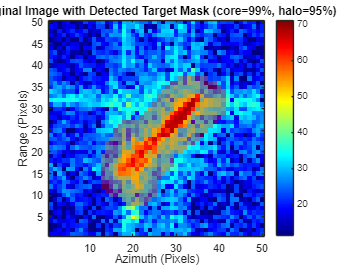


if nnz(background_mask) < 1000
    warning('Background mask has <1000 pixels: consider lowering core_pct/halo_pct or GuardCells.');
end

% --- Visualize mask overlay ---
figure('Color','w', 'Name', 'Target Detection Validation');
imagesc(mag0_db); axis image; colormap(jet); colorbar;
set(gca,'YDir','normal'); caxis(clim);
title(sprintf('Original Image with Detected Target Mask (core=%d%%, halo=%d%%)', core_pct, halo_pct));
xlabel('Azimuth (Pixels)'); ylabel('Range (Pixels)');
hold on;

% overlay mask as semi-transparent red
h_mask = imagesc(double(target_mask));
set(h_mask, 'AlphaData', target_mask * 0.35);      % 35% opacity on masked pixels
set(h_mask, 'CData', cat(3, ones(rows,cols), zeros(rows,cols), zeros(rows,cols)));  % RGB red


% ------------------------------------------------------------------------
% STEP 2: BACKGROUND STATS (used for synthetic generation)
% ------------------------------------------------------------------------
background_vals = mag0(background_mask);
if nnz(background_vals) < 1000
    error('Insufficient background pixels detected for statistical analysis.');
end

mu  = median(background_vals(:));
sig = 1.4826 * median(abs(background_vals(:) - mu) + eps); 
hi  = prctile(background_vals, 98); 
lo  = max(prctile(background_vals, 5), 0);
fprintf('Estimated Clutter Stats (Mag): Mu=%.4f, Sig=%.4f, lo=%.4f, hi=%.4f\n', mu, sig, lo, hi);

Estimated Clutter Stats (Mag): Mu=13.0936, Sig=9.2966, lo=3.2681, hi=55.5134



% ------------------------------------------------------------------------
% STEP 3: SYNTHESIZE FULL-SIZE CLUTTER IMAGE (100%% Synthetic)
% (your original multi-scale synthesis preserved)
% ------------------------------------------------------------------------
rng(42);
num_scales = 3;
noise_tex  = zeros(rows, cols);

for i = 1:num_scales
    sigma_scale = 1.2 * (2^(i-1)); 
    weight      = 1 / sigma_scale;
    base_noise  = randn(rows, cols);      % different base per scale → richer texture
    noise_tex   = noise_tex + weight * imgaussfilt(base_noise, sigma_scale);
end

% Normalize and shape to background stats
noise_tex = noise_tex - mean(noise_tex(:));
noise_tex = (noise_tex / std(noise_tex(:) + eps)) * sig + mu;
noise_tex = abs(noise_tex);
noise_tex = min(max(noise_tex, lo), hi);

% Random phase for complex field
rand_phase    = exp(1j * (2*pi*rand(rows, cols)));
sar_synthetic = noise_tex .* rand_phase;

% Here, "camouflaged" is just fully synthetic clutter
sar_camouflaged = sar_synthetic; 
mag1   = abs(sar_camouflaged);

% ------------------------------------------------------------------------
% dB images and common dynamic range
% ------------------------------------------------------------------------
mag0_db = 20*log10(mag0 + eps);
mag1_db = 20*log10(mag1 + eps);
top_db  = max(mag0_db(:));
dr_db   = 60;
clim    = [top_db - dr_db, top_db];

% ------------------------------------------------------------------------
% STEP 4: STATISTICAL VALIDATION
% ------------------------------------------------------------------------
disp(' ');

disp('=====================================================');

disp('   STATISTICAL VALIDATION: BACKGROUND vs. SYNTHETIC  ');

   STATISTICAL VALIDATION: BACKGROUND vs. SYNTHETIC  


disp('=====================================================');


% --- 4.1 First-Order Stats ---
fprintf('\n--- First-Order Statistics (Linear Magnitude) ---\n');


--- First-Order Statistics (Linear Magnitude) ---



bk_mean    = mean(background_vals(:));
bk_std     = std(background_vals(:));
synth_mean = mean(mag1(:));
synth_std  = std(mag1(:));

T = table(bk_mean, synth_mean, abs(bk_mean - synth_mean), ...
          bk_std, synth_std, abs(bk_std - synth_std), ...
          'VariableNames', {'Bk_Mean', 'Synth_Mean', 'Mean_Diff', 'Bk_STD', 'Synth_STD', 'STD_Diff'});
T.Properties.RowNames = {'Comparison'};
disp(T(:, {'Bk_Mean', 'Synth_Mean', 'Bk_STD', 'Synth_STD'}));

                  Bk_Mean    Synth_Mean    Bk_STD    Synth_STD
                  _______    __________    ______    _________

    Comparison    17.102       13.979      14.413     7.9477  



fprintf('Mean Difference: %.4f | STD Difference: %.4f\n', T.Mean_Diff(1), T.STD_Diff(1));

Mean Difference: 3.1232 | STD Difference: 6.4653



% --- 4.2 Histograms ---
figure('Color','w', 'Name', 'Statistical Analysis');

subplot(2,2,1); 
histogram(background_vals, 'Normalization', 'pdf', 'BinWidth', 0.05, ...
          'FaceColor', [0 0.4470 0.7410], 'EdgeColor', 'k'); hold on;
histogram(mag1(:), 'Normalization', 'pdf', 'BinWidth', 0.05, ...
          'FaceColor', [0.8500 0.3250 0.0980], 'EdgeColor', 'k', 'FaceAlpha', 0.5); 
title('Magnitude Distribution Comparison');
xlabel('Linear Magnitude |S|'); ylabel('Probability Density');
legend('True Background Sample', 'Synthetic Image (100%)');
grid on;

% --- 4.3 ACF ---
fprintf('\n--- Second-Order Statistics (Autocorrelation) ---\n');


--- Second-Order Statistics (Autocorrelation) ---



max_patch_size = 128; 
rows_valid     = rows - max_patch_size;
cols_valid     = cols - max_patch_size;

patch_found = false;
max_attempts = 100;
for attempt = 1:max_attempts
    r = randi([1, max(1, rows_valid)]);
    c = randi([1, max(1, cols_valid)]);
    if r + max_patch_size - 1 > rows || c + max_patch_size - 1 > cols
        continue;
    end
    patch_check = background_mask(r:r+max_patch_size-1, c:c+max_patch_size-1);
    if all(patch_check(:))
        row_start = r;
        col_start = c;
        patch_size = max_patch_size;
        patch_found = true;
        break;
    end
end

if ~patch_found
    warning('Could not find a 100%% clean background patch. Using a smaller, slightly contaminated patch.');
    [r_idx, c_idx] = find(background_mask, 1);
    row_start = r_idx;
    col_start = c_idx;
    patch_size = min(max_patch_size, min(rows-r_idx, cols-c_idx));
end


Bk_Patch    = mag0(row_start:row_start+patch_size-1, col_start:col_start+patch_size-1);
Synth_Patch = mag1(row_start:row_start+patch_size-1, col_start:col_start+patch_size-1);
fprintf('ACF patch size used: %dx%d\n', size(Bk_Patch, 1), size(Bk_Patch, 2));

ACF patch size used: 49x49


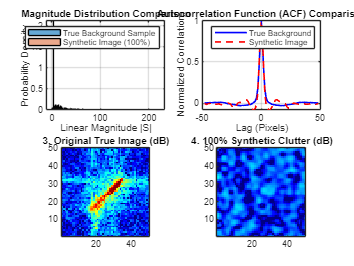


ACF_Bk    = xcorr2(Bk_Patch    - mean(Bk_Patch(:)));
ACF_Synth = xcorr2(Synth_Patch - mean(Synth_Patch(:)));

ACF_Bk    = ACF_Bk    / (ACF_Bk(ceil(end/2),   ceil(end/2))   + eps);
ACF_Synth = ACF_Synth / (ACF_Synth(ceil(end/2), ceil(end/2)) + eps);

mid_row   = ceil(size(ACF_Bk, 1) / 2);
slice_len = 50;
mid_col   = ceil(size(ACF_Bk, 2) / 2);
slice_start = max(1, mid_col - slice_len);
slice_end   = min(size(ACF_Bk,2), mid_col + slice_len);

ACF_Bk_slice    = ACF_Bk(mid_row,    slice_start:slice_end);
ACF_Synth_slice = ACF_Synth(mid_row, slice_start:slice_end);
lags = (slice_start:slice_end) - mid_col;

subplot(2,2,2);
plot(lags, ACF_Bk_slice, 'b', 'LineWidth', 1.5); hold on;
plot(lags, ACF_Synth_slice, 'r--', 'LineWidth', 1.5);
title('Autocorrelation Function (ACF) Comparison');
xlabel('Lag (Pixels)'); ylabel('Normalized Correlation');
legend('True Background', 'Synthetic Image');
grid on;

% --- 4.4 Full-image visual check ---
subplot(2,2,3); imagesc(mag0_db); axis image; colormap(jet); caxis(clim);
set(gca,'YDir','normal'); title('3. Original True Image (dB)');

subplot(2,2,4); imagesc(mag1_db); axis image; colormap(jet); caxis(clim);
set(gca,'YDir','normal'); title('4. 100% Synthetic Clutter (dB)');


% --- SAVE RESULT (complex) ---
filename = sprintf('desired_attacked_complex_%s.mat', sar_algo);
save(filename, 'sar_camouflaged');
fprintf('\nSaved 100%% fully synthetic clutter image to %s\n', filename);


Saved 100% fully synthetic clutter image to desired_attacked_complex_LIA.mat



disp('Validation complete: Check figures for statistical match.');

Validation complete: Check figures for statistical match.


### This MATLAB script is designed to **load and visually compare** a **True (Original) Complex SAR Image** against a **Desired Attacked (Camouflaged) Complex SAR Image** side-by-side.

clc; clear; close all;

%% ------------------ User Settings ----------------------
sar_algo = 'MFA';        % 'MFA', 'RMA', or 'BPA'
dx = 1;                  % horizontal pixel spacing (mm)
dy = 1;                  % vertical pixel spacing (mm)
bbox = [-500 500 -500 500];  % [x_min x_max y_min y_max] in mm
use_flip = true;         % true = fliplr for display (optional)
%% -------------------------------------------------------

fprintf('SAR Algorithm: %s\n', sar_algo);

% --- Filenames ---
filename_true    = sprintf('trueImage_complex_%s.mat', sar_algo);
filename_attacked = sprintf('desired_attacked_complex_%s.mat', sar_algo);

% --- Load TRUE image ---
try
    S_true = load(filename_true);
    fprintf('Loaded TRUE file: %s\n', filename_true);
    sar_true = S_true.trueImage_complex;
catch ME
    error('Could not load TRUE file %s. Error: %s', filename_true, ME.message);
end

% --- Load ATTACKED image ---
try
    S_atk = load(filename_attacked);
    fprintf('Loaded ATTACKED file: %s\n', filename_attacked);
    sar_atk = S_atk.sar_camouflaged;
catch ME
    error('Could not load ATTACKED file %s. Error: %s', filename_attacked, ME.message);
end

% --- Magnitude images (linear scale) ---
mag_true = abs(sar_true);
mag_atk  = abs(sar_atk);

if use_flip
    mag_true = fliplr(mag_true);
    mag_atk  = fliplr(mag_atk);
end

% --- Shared color limits (linear) ---
top_val = max([mag_true(:); mag_atk(:)]);
clim    = [0, top_val];   % from 0 to global max

% --- Plot both using your mesh-based helper ---
figure('Color','w','Name',['SAR Comparison (|S| Magnitude) - ' sar_algo]);

subplot(1,2,1);
plot_sar(mag_true, bbox, dx, dy, '1. True Image (|S|)');
caxis(clim); colorbar; colormap(jet);

subplot(1,2,2);
plot_sar(mag_atk, bbox, dx, dy, '2. Desired Attacked Image (|S|)');
caxis(clim); colorbar; colormap(jet);

sgtitle(['True vs Desired Attacked Image (' sar_algo ') - Linear |S| Magnitude']);

% -------------------------------------------------------
function plot_sar(sarImage, bbox, dx, dy, plotTitle)
    % Helper for standard mesh plot
    xv = bbox(1) + (0:size(sarImage, 2) - 1) * dx;
    yv = bbox(3) + (0:size(sarImage, 1) - 1) * dy;
    mesh(xv, yv, sarImage, 'FaceColor', 'interp', 'LineStyle', 'none');
    view(2);
    axis equal tight;
    colormap('jet');
    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    title(plotTitle);
    xlim([bbox(1) bbox(2)]);
    ylim([bbox(3) bbox(4)]);
end



function plot_sar_db(mag_true, mag_atk, bbox, dx, dy)
    % Compute dB scale magnitudes
    mag0_db = 20*log10(mag_true + eps);
    mag1_db = 20*log10(mag_atk  + eps);

    % Use common color scale for fair comparison
    top_db = max([mag0_db(:); mag1_db(:)]);  % shared max
    dr_db  = 60;                             % dynamic range
    clim   = [top_db - dr_db, top_db];

    % Define coordinate grid
    xv = bbox(1) + (0:size(mag_true,2)-1) * dx;
    yv = bbox(3) + (0:size(mag_true,1)-1) * dy;

    % Create figure
    figure('Color','w','Name','SAR Comparison (Shared dB Scale)');

    % --- Plot TRUE image ---
    subplot(1,2,1);
    imagesc(xv, yv, mag0_db);
    axis equal tight;
    set(gca,'YDir','normal');
    colormap(jet); colorbar; caxis(clim);
    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    title('1. True Image (dB)');
    xlim([bbox(1), bbox(2)]);
    ylim([bbox(3), bbox(4)]);

    % --- Plot ATTACKED image ---
    subplot(1,2,2);
    imagesc(xv, yv, mag1_db);
    axis equal tight;
    set(gca,'YDir','normal');
    colormap(jet); colorbar; caxis(clim);
    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    title('2. Desired Attacked Image (dB)');
    xlim([bbox(1), bbox(2)]);
    ylim([bbox(3), bbox(4)]);

    sgtitle('True vs Desired Attacked Image (Shared dB Color Scale)');
end


% clc; clear; close all; % Clear figures too! 
% 
% sar_algo = 'MFA';  % Options: 'MFA', 'RMA', 'BPA'
% fprintf('SAR Algorithm: %s\n', sar_algo);
% 
% % -------------------------------------------------------------------------
% % 0. Detection parameters for background/object separation
% % -------------------------------------------------------------------------
% core_pct  = 99;   % percentile for bright "core" of object
% halo_pct  = 95;   % percentile for halo region
% GuardCells = 50;  % dilation radius around detected object (pixels)
% min_area   = 10;  % minimum connected area (pixels) to keep as object
% 
% % --- 1. Define File Names ---
% filename_true    = sprintf('trueImage_complex_%s.mat', sar_algo);
% filename_attacked = sprintf('desired_attacked_complex_%s.mat', sar_algo);
% 
% % --- 2. Load True (Original) Image ---
% try
%     S_true = load(filename_true);
%     disp(['Successfully loaded True file: ', filename_true]);
%     sarImage_true = S_true.trueImage_complex; % Assuming variable name is 'trueImage_complex'
% catch ME
%     error('Could not load TRUE file %s. Error: %s', filename_true, ME.message);
% end
% 
% % --- 3. Load Desired Attacked Image ---
% try
%     S_atk = load(filename_attacked);
%     disp(['Successfully loaded Attacked file: ', filename_attacked]);
%     sarImage_atk = S_atk.sar_camouflaged; % Assuming variable name is 'sar_camouflaged'
% catch ME
%     error('Could not load ATTACKED file %s. Error: %s', filename_attacked, ME.message);
% end
% 
% % --- 4. Common parameters for plotting ---
% dx = 1;
% dy = 1;
% bbox = [-500 500 -500 500]; % Bounding box (mm) for MFA/RMA/BPA
% 
% % --- 5. Determine plotting function ---
% plot_func    = @plot_sar;
% title_suffix = '';
% if strcmpi(sar_algo, 'BPA')
%     plot_func    = @plot_sar_bpa;
%     title_suffix = ' (dlBPA)';
% end
% 
% % --- 6. Magnitudes (no flip yet; we’ll flip only for display) ---
% mag_true_full = abs(sarImage_true);
% mag_atk_full  = abs(sarImage_atk);
% 
% % -------------------------------------------------------------------------
% % A. AUTOMATIC OBJECT DETECTION ON TRUE IMAGE (to get background mask)
% % -------------------------------------------------------------------------
% [rows, cols] = size(mag_true_full);
% mag_true_db  = 20*log10(mag_true_full + eps);
% top_db       = max(mag_true_db(:));
% dr_db        = 60;
% clim         = [top_db - dr_db, top_db];
% 
% fprintf('\nRunning object/background separation on TRUE image...\n');
% 
% % Core threshold (very bright pixels)
% core_thr_db  = prctile(mag_true_db(:), core_pct);
% mask_core    = mag_true_db > core_thr_db;
% 
% % Clean small speckles
% se_small     = strel('disk', 2);
% mask_core    = imclose(mask_core, se_small);
% CC           = bwconncomp(mask_core);
% stats        = regionprops(CC,'Area');
% keep_idx     = find([stats.Area] >= min_area);
% obj_core_clean = false(size(mask_core));
% for k = keep_idx
%     obj_core_clean(CC.PixelIdxList{k}) = true;
% end
% 
% % Halo threshold (softer region around object)
% halo_thr_db  = prctile(mag_true_db(:), halo_pct);
% halo_cand    = mag_true_db > halo_thr_db;
% 
% % Region growing: grow from core into halo candidates
% obj_mask_rg = imreconstruct(obj_core_clean, halo_cand);
% 
% % Dilate to give a generous object+halo boundary
% se_guard    = strel('disk', GuardCells);
% obj_mask    = imdilate(obj_mask_rg, se_guard);
% 
% % Background mask: everything not object
% bg_mask = ~obj_mask;
% fprintf('Object pixels (with halo): %d\n', nnz(obj_mask));
% fprintf('Background pixels:         %d\n', nnz(bg_mask));
% 
% if nnz(bg_mask) < 1000
%     warning('Background mask has <1000 pixels. Consider tuning core_pct/halo_pct/GuardCells.');
% end
% 
% % --- Visualize detection on TRUE image ---
% figure('Color','w','Name','True Image + Object Mask');
% imagesc(mag_true_db); axis image; colormap(jet); colorbar;
% set(gca,'YDir','normal'); caxis(clim);
% title(sprintf('True Image with Object Mask (core=%d%%, halo=%d%%)', core_pct, halo_pct));
% xlabel('Azimuth (px)'); ylabel('Range (px)');
% hold on;
% h_mask = imagesc(double(obj_mask));
% set(h_mask,'AlphaData', obj_mask*0.35); % 35% opacity
% set(h_mask,'CData', cat(3, ones(rows,cols), zeros(rows,cols), zeros(rows,cols))); % red overlay
% 
% % -------------------------------------------------------------------------
% % B. BACKGROUND STATISTICS: TRUE vs ATTACKED
% % -------------------------------------------------------------------------
% bg_true_vals = mag_true_full(bg_mask);
% bg_atk_vals  = mag_atk_full(bg_mask);   % same spatial region in attacked image
% 
% % First-order stats
% bk_mean_true = mean(bg_true_vals(:));
% bk_std_true  = std(bg_true_vals(:));
% bk_mean_atk  = mean(bg_atk_vals(:));
% bk_std_atk   = std(bg_atk_vals(:));
% 
% fprintf('\n========== BACKGROUND STATISTICS (NO OBJECT REGION) ==========\n');
% fprintf('Background pixels: %d\n', nnz(bg_mask));
% fprintf('True  BG: mean = %.6g, std = %.6g\n', bk_mean_true, bk_std_true);
% fprintf('Atk   BG: mean = %.6g, std = %.6g\n', bk_mean_atk,  bk_std_atk);
% fprintf('Diff     : |mean| = %.6g, |std| = %.6g\n', ...
%         abs(bk_mean_true - bk_mean_atk), abs(bk_std_true - bk_std_atk));
% 
% % Optionally, compute simple similarity metrics on background area
% bg_mse = mean((double(bg_true_vals(:)) - double(bg_atk_vals(:))).^2);
% if bg_mse > 0
%     maxv = max(double(bg_true_vals(:)));
%     bg_psnr = 10*log10(maxv^2 / bg_mse);
% else
%     bg_psnr = Inf;
% end
% fprintf('Background MSE  = %.6g\n', bg_mse);
% fprintf('Background PSNR = %.3f dB\n', bg_psnr);
% 
% % Histogram comparison of background-only regions
% figure('Color','w','Name','Background-Only Histograms');
% histogram(bg_true_vals, 'Normalization','pdf','BinWidth',0.05, ...
%           'FaceColor',[0 0.4470 0.7410],'EdgeColor','k'); hold on;
% histogram(bg_atk_vals, 'Normalization','pdf','BinWidth',0.05, ...
%           'FaceColor',[0.8500 0.3250 0.0980],'EdgeColor','k','FaceAlpha',0.5);
% title('Background-Only Magnitude Distribution');
% xlabel('|S| (linear magnitude)'); ylabel('PDF');
% legend('True Background','Attacked Background');
% grid on;
% 
% % -------------------------------------------------------------------------
% % C. SIDE-BY-SIDE VISUAL COMPARISON (your original plotting)
% % -------------------------------------------------------------------------
% % Use fliplr only for visualization if your plot_sar expects that
% mag_true_vis = fliplr(mag_true_full);
% mag_atk_vis  = fliplr(mag_atk_full);
% 
% figure('Color', 'w', 'Name', ['SAR Comparison: ' sar_algo]);
% 
% subplot(1, 2, 1);
% plot_func(mag_true_vis, bbox, dx, dy, ['1. True Image' title_suffix]);
% 
% subplot(1, 2, 2);
% plot_func(mag_atk_vis,  bbox, dx, dy, ['2. Desired Attacked Image' title_suffix]);
% 
% disp('Plotting complete. Check figures for comparison and background stats.');


% clc; clear; close all;
% 
% %% ------------------ User Settings ----------------------
% sar_algo = 'MFA';        % 'MFA', 'RMA', or 'BPA'
% dx = 1;                  % horizontal pixel spacing (mm)
% dy = 1;                  % vertical pixel spacing (mm)
% bbox = [-500 500 -500 500];  % [x_min x_max y_min y_max] in mm
% use_flip = true;         % true = fliplr for display (optional)
% %% -------------------------------------------------------
% 
% fprintf('SAR Algorithm: %s\n', sar_algo);
% 
% % --- Filenames ---
% filename_true    = sprintf('trueImage_complex_%s.mat', sar_algo);
% filename_attacked = sprintf('desired_attacked_complex_%s.mat', sar_algo);
% 
% % --- Load TRUE image ---
% try
%     S_true = load(filename_true);
%     fprintf('Loaded TRUE file: %s\n', filename_true);
%     sar_true = S_true.trueImage_complex;
% catch ME
%     error('Could not load TRUE file %s. Error: %s', filename_true, ME.message);
% end
% 
% % --- Load ATTACKED image ---
% try
%     S_atk = load(filename_attacked);
%     fprintf('Loaded ATTACKED file: %s\n', filename_attacked);
%     sar_atk = S_atk.sar_camouflaged;
% catch ME
%     error('Could not load ATTACKED file %s. Error: %s', filename_attacked, ME.message);
% end
% 
% % --- Compute magnitudes ---
% mag_true = abs(sar_true);
% mag_atk  = abs(sar_atk);
% 
% if use_flip
%     mag_true = fliplr(mag_true);
%     mag_atk  = fliplr(mag_atk);
% end
% 
% % --- Call the shared-scale plotting function ---
% plot_sar_db(mag_true, mag_atk, bbox, dx, dy);



Old version 

clc; clear; close all; % Clear figures too!

sar_algo = 'MFA';  % Options: 'MFA', 'RMA', 'BPA'
fprintf('SAR Algorithm: %s\n', sar_algo);

% --- 1. Define File Names ---
filename_true = sprintf('trueImage_complex_%s.mat', sar_algo);
filename_attacked = sprintf('desired_attacked_complex_%s.mat', sar_algo);

% --- 2. Load True (Original) Image ---
try
    S_true = load(filename_true);
    disp(['Successfully loaded True file: ', filename_true]);
    sarImage_true = S_true.trueImage_complex; % Assuming variable name is 'trueImage_complex'
catch ME
    error('Could not load TRUE file %s. Error: %s', filename_true, ME.message);
end

% --- 3. Load Desired Attacked Image ---
try
    S_atk = load(filename_attacked);
    disp(['Successfully loaded Attacked file: ', filename_attacked]);
    sarImage_atk = S_atk.sar_camouflaged; % Assuming variable name is 'sar_camouflaged'
catch ME
    error('Could not load ATTACKED file %s. Error: %s', filename_attacked, ME.message);
end

% --- 4. Define Common Parameters ---
% Parameters often used in your custom plot functions
dx = 1;
dy = 1;
bbox = [-500 500 -500 500]; % Bounding box (mm) for MFA/RMA/BPA

% --- 5. Determine Plotting Function and Call Both Plots ---
plot_func = @plot_sar;
title_suffix = '';

if strcmp(upper(sar_algo), 'BPA')
    plot_func = @plot_sar_bpa;
    title_suffix = ' (dlBPA)';
end

% Ensure magnitude is used and fliplr (if necessary for display convention)
mag_true = fliplr(abs(sarImage_true));
mag_atk = fliplr(abs(sarImage_atk));

% Create a new figure for side-by-side comparison
figure('Color', 'w', 'Name', ['SAR Comparison: ' sar_algo]);

% --- Plot 1: True (Original) Image ---
subplot(1, 2, 1);
plot_func(mag_true, bbox, dx, dy, ['1. True Image' title_suffix]);

% --- Plot 2: Desired Attacked (Camouflaged) Image ---
subplot(1, 2, 2);
plot_func(mag_atk, bbox, dx, dy, ['2. Desired Attacked Image' title_suffix]);

disp('Plotting complete. Check the figure window for comparison.');

% bbox = [-500 500 -500 500]; dx = 1; dy = 1;
% trueImageX = bbox(1) + (0 : size(sarImage, 2) - 1) * dx;  % width
% trueImageY = bbox(3) + (0 : size(sarImage, 1) - 1) * dy;  % height 
% 
% % Plot SAR image
% figure
% mesh(bbox(1) + (0:size(sarImage, 2) - 1) * dx, ...
%      bbox(3) + (0:size(sarImage, 1) - 1) * dy, ...
%      sarImage, 'FaceColor', 'interp', 'LineStyle', 'none');
% view(2) 
% colormap('jet'); 
% axis equal
% xlabel('Horizontal (mm)'); ylabel('Vertical (mm)'); title('Desired Attacked Image: ', sar_algo)
% xlim([bbox(1) bbox(2)]); ylim([bbox(3) bbox(4)]);

function plot_sar_bpa(I_plot, bbox, dx, dy, plotTitle)
    % PLOT_SAR_BPA: Plots the image, using linspace to define axes based on bbox.
    % This structure is consistent with how BPA often defines its grid.
    %
    % I_plot: B x A image (vertical x horizontal)
    % bbox : [xmin xmax ymin ymax] in mm
    % dx,dy: mm per pixel - NOTE: dx/dy are primarily used for coordinate scaling
    %                             in this linspace approach, they are implicitly
    %                             defined by bbox and A/B.

    % Get image dimensions B x A (Vertical x Horizontal pixels)
    [B, A] = size(I_plot);

    % --- 1. Define Image Coordinates using LINSPACE ---
    % Since bbox is in mm, wh1/wh2 will also be in mm.
    % We use A and B (horizontal and vertical size) to define the spacing.
    % The coordinates are automatically in mm.
    xv = linspace(bbox(1), bbox(2), A); % Horizontal axes (mm)
    yv = linspace(bbox(3), bbox(4), B); % Vertical axes (mm)

    % --- 2. Execute Plot (similar to your desired format) ---
    %figure;
    mesh(xv, yv, I_plot, 'FaceColor', 'interp', 'LineStyle', 'none');
    
    view(2);
    colormap('jet');
    axis equal tight; % Use 'tight' to fit data limits
    
    xlabel('Horizontal (mm)');
    ylabel('Vertical (mm)');
    title(plotTitle);

    xlim([bbox(1) bbox(2)]);
    ylim([bbox(3) bbox(4)]);
end


% function plot_sar_bpa(I_plot, bbox, dx, dy, plotTitle)
%     % I_plot: B x A image (vertical x horizontal)
%     % bbox : [xmin xmax ymin ymax] in mm
%     % dx,dy: mm per pixel
% 
%     % x / y axes in mm
%     xv = bbox(1) + (0:size(I_plot, 2)-1) * dx;
%     yv = bbox(3) + (0:size(I_plot, 1)-1) * dy;
% 
%     mesh(xv, yv, I_plot, 'FaceColor', 'interp', 'LineStyle', 'none');
%     view(2);
%     colormap('jet');
%     axis equal tight;
%     xlabel('Horizontal (mm)');
%     ylabel('Vertical (mm)');
%     title(plotTitle);
% 
%     xlim([bbox(1) bbox(2)]);
%     ylim([bbox(3) bbox(4)]);
% end



% function plot_sar(sarImage, bbox, dx, dy, plotTitle)
% % Helper for standard mesh plot
%     xv = bbox(1) + (0:size(sarImage, 2) - 1) * dx;
%     yv = bbox(3) + (0:size(sarImage, 1) - 1) * dy;
%     mesh(xv, yv, sarImage, 'FaceColor', 'interp', 'LineStyle', 'none');
%     view(2); colormap('jet');
%     axis equal tight; xlabel('Horizontal (mm)'); ylabel('Vertical (mm)');
%     title(plotTitle); xlim([bbox(1) bbox(2)]); ylim([bbox(3) bbox(4)]);
% end

#### Do some analysis between the clean and manually generated atk images 

clc; clear; 

sar_algo = 'RMA';

% --- Dynamically construct filenames ---
% Assuming the clean image file is: 'trueImage_complx_RMA.mat'
filename_orig = sprintf('trueImage_complex_%s.mat', sar_algo);

% Assuming the camouflaged image file is: 'trueImage_complx_camouflaged_RMA.mat'
filename_atk = sprintf('desired_attacked_complex_%s.mat', sar_algo);

% --- Load Original Data ---
if isfile(filename_orig)
    S0 = load(filename_orig);
    % Dynamically check for the variable name: 'trueImage_complx' (assuming this is the name inside the .mat file)
    assert(isfield(S0, 'trueImage_complex'), ['Variable ''trueImage_complex'' not found in ', filename_orig]);
    orig = S0.trueImage_complex;
    if isa(orig, 'dlarray'); orig = extractdata(orig); end % Handle dlarray if present
    disp(['Loaded original image from: ', filename_orig]);
else
    error('Original file not found: %s', filename_orig);
end

% --- Load Camouflaged Data ---
if isfile(filename_atk)
    S1 = load(filename_atk);
    % Dynamically check for the variable name: 'sar_camouflaged' (assuming this is the name inside the .mat file)
    assert(isfield(S1, 'sar_camouflaged'), ['Variable ''sar_camouflaged'' not found in ', filename_atk]);
    atk = S1.sar_camouflaged;
    if isa(atk, 'dlarray'); atk = extractdata(atk); end % Handle dlarray if present
    disp(['Loaded camouflaged image from: ', filename_atk]);
else
    error('Camouflaged file not found: %s', filename_atk);
end

% --- Basic checks ---
if ~isequal(size(orig), size(atk))
    error('Original and camouflaged images have different sizes.');
end
[NpixY, NpixX] = size(orig);

% --- Magnitude & phase ---
mag0 = abs(orig);        mag1 = abs(atk);
ph0  = angle(orig);     ph1  = angle(atk);

% --- Difference maps ---
mag_diff = mag1 - mag0;              % linear magnitude diff
mag_db0 = 20*log10(mag0 + eps);
mag_db1 = 20*log10(mag1 + eps);
mag_db_diff = mag_db1 - mag_db0;     % dB difference
phase_diff = angle(exp(1j*(ph1-ph0))); % wrapped phase difference

% --- Auto-detect attacked region by large mag change ---
% threshold = robust estimate (e.g. 4*MAD of outside)
mad_all = mad(mag_db_diff(:),1);
thresh = max(3, 4*mad_all); % dB threshold (tune if needed)
mask_auto = abs(mag_db_diff) > thresh;

% Clean mask (remove tiny islands)
mask_auto = bwareaopen(mask_auto, 50);   % remove <50 px
mask_auto = imfill(mask_auto, 'holes');  % fill holes

% If mask empty, relax threshold
if nnz(mask_auto) < 10
    thresh = max(1.5, 2*mad_all);
    mask_auto = abs(mag_db_diff) > thresh;
    mask_auto = bwareaopen(mask_auto, 20);
    mask_auto = imfill(mask_auto,'holes');
end

% --- Define background ring region for comparison ---
se_outer = strel('disk', 10);
mask_outer = imdilate(mask_auto, se_outer);
ring = mask_outer & ~mask_auto;
ring = bwareaopen(ring, 20);

% --- Pixel sets ---
pix_mask = mag0(mask_auto);
pix_ring = mag0(ring);
pix_outside = mag0(~(mask_auto | ring)); % rest of image

% --- Basic descriptive stats function ---
stats = @(x) struct(...
    'N', numel(x),...
    'mean', mean(x(:)),...
    'median', median(x(:)),...
    'std', std(x(:)),...
    'mad', mad(x(:),1),...
    'min', min(x(:)),...
    'max', max(x(:)));

s_mask   = stats(pix_mask);
s_ring   = stats(pix_ring);
s_outside= stats(pix_outside);
s_all0   = stats(mag0(:));
s_all1   = stats(mag1(:));

% --- Additional metrics ---
% Pixel-wise correlation and linear fit (mag)
x = mag0(:); y = mag1(:);
R = corrcoef(x,y);  Rval = R(1,2);
coeffs = polyfit(x,y,1);
yhat = polyval(coeffs,x);
SSres = sum((y - yhat).^2);
SStot = sum((y - mean(y)).^2);
Rsq = 1 - SSres/SStot;

% MSE / PSNR on magnitude (common image metrics)
mse_mag = immse(mat2gray(mag0), mat2gray(mag1));
try
    [psnr_val, ~] = psnr(mat2gray(mag1), mat2gray(mag0));
catch
    psnr_val = 10*log10(1/max(mse_mag,eps)); % fallback
end

% KS-test between mask and ring magnitudes (two-sample)
try
    [h_ks, p_ks] = kstest2(pix_mask(:), pix_ring(:));
catch
    h_ks = NaN; p_ks = NaN;
end

% --- Print summary ---
fprintf('\n--- Summary statistics ---\n');
fprintf('Masked region: N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_mask.N, s_mask.mean, s_mask.median, s_mask.std);
fprintf('Ring region:   N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_ring.N, s_ring.mean, s_ring.median, s_ring.std);
fprintf('Outside region:N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_outside.N, s_outside.mean, s_outside.median, s_outside.std);
fprintf('Global orig mean=%.4f, cam mean=%.4f\n', s_all0.mean, s_all1.mean);
fprintf('Correlation (mag): R=%.4f, linear fit y=%.4f*x + %.4f, R^2=%.4f\n', Rval, coeffs(1), coeffs(2), Rsq);
fprintf('MSE (mag, scaled)=%.6g, PSNR(dB)~=%.2f dB\n', mse_mag, psnr_val);
fprintf('KS-test (mask vs ring) reject H0? %d, p=%.3g\n', h_ks, p_ks);

% --- Create figures ---
outdir = 'analysis_figs';
if ~exist(outdir,'dir'), mkdir(outdir); end

% 1) Before / After (dB) and detected mask overlay
f1 = figure('Units','normalized','Position',[0.05 0.05 0.7 0.6]);
subplot(1,3,1); imagesc(mag_db0); axis image; set(gca,'YDir','normal'); colormap(jet); colorbar;
title('Original mag (dB)');
subplot(1,3,2); imagesc(mag_db1); axis image; set(gca,'YDir','normal'); colormap(jet); colorbar;
title('Camouflaged mag (dB)');
subplot(1,3,3); imagesc(mag_db_diff); axis image; set(gca,'YDir','normal'); colormap(parula); colorbar;
title('Mag dB diff (cam - orig)');
hold on;
% overlay mask contour on the difference panel
[contx,conty] = contourmask(mask_auto);
if ~isempty(contx)
    subplot(1,3,3); hold on; plot(contx, conty, 'r', 'LineWidth', 1.2);
end
saveas(f1, fullfile(outdir,'before_after_diff_mask.png'));

% 2) Histogram & CDF: mask vs ring vs outside (magnitude)
f2 = figure('Units','normalized','Position',[0.1 0.1 0.6 0.6]);
edges = linspace(0, max(mag0(:))*1.1, 120);
h1 = histogram(pix_mask, edges, 'Normalization','pdf','DisplayStyle','stairs','LineWidth',1.5); hold on;
h2 = histogram(pix_ring, edges, 'Normalization','pdf','DisplayStyle','stairs','LineWidth',1.5);
h3 = histogram(pix_outside, edges, 'Normalization','pdf','DisplayStyle','stairs','LineWidth',1.5);
legend('Mask','Ring','Outside'); xlabel('Magnitude'); ylabel('PDF'); title('Magnitude distributions');
saveas(f2, fullfile(outdir,'magnitude_histograms.png'));

% CDF
f2b = figure('Units','normalized','Position',[0.2 0.2 0.5 0.4]);
[f_mask, x_mask] = ecdf(pix_mask);
[f_ring, x_ring] = ecdf(pix_ring);
[f_out, x_out] = ecdf(pix_outside);
plot(x_mask, f_mask, '-', 'LineWidth', 1.5); hold on;
plot(x_ring, f_ring, '-', 'LineWidth', 1.5);
plot(x_out, f_out, '-', 'LineWidth', 1.5);
legend('Mask','Ring','Outside'); xlabel('Magnitude'); ylabel('CDF'); title('Empirical CDFs');
saveas(f2b, fullfile(outdir,'magnitude_cdfs.png'));

% 3) Scatter: original vs camouflaged magnitude (downsample for plotting)
nplot = min(20000, numel(x));
idx = randperm(numel(x), nplot);
f3 = figure('Units','normalized','Position',[0.1 0.1 0.5 0.5]);
scatter(x(idx), y(idx), 8, '.'); axis equal;
xlabel('Original mag'); ylabel('Camouflaged mag'); title(sprintf('Scatter (R=%.3f, R^2=%.3f)', Rval, Rsq));
% show unity line and linear fit
hold on; xl = xlim; plot(xl, xl, '--k'); plot(xl, polyval(coeffs,xl), '-r','LineWidth',1.2);
saveas(f3, fullfile(outdir,'mag_scatter.png'));

% 4) Phase histograms and diff map
f4 = figure('Units','normalized','Position',[0.1 0.1 0.6 0.4]);
subplot(1,3,1); histogram(ph0(mask_auto), 60); title('Phase orig (mask)'); xlabel('rad');
subplot(1,3,2); histogram(ph1(mask_auto), 60); title('Phase cam (mask)'); xlabel('rad');
subplot(1,3,3); imagesc(phase_diff); axis image; set(gca,'YDir','normal'); colorbar; title('Phase diff (wrapped)');
saveas(f4, fullfile(outdir,'phase_stats.png'));

% 5) Spatial map of auto mask
f5 = figure('Units','normalized','Position',[0.2 0.2 0.4 0.4]);
imagesc(mag_db1); axis image; set(gca,'YDir','normal'); colormap(jet); colorbar;
hold on; h = imshow(mask_auto); set(h,'AlphaData',0.25); title('Detected attack mask overlay');
saveas(f5, fullfile(outdir,'mask_overlay.png'));

% 6) Boxplots of magnitude by region
f6 = figure('Units','normalized','Position',[0.1 0.1 0.6 0.5]);
boxplot([pix_mask(:); pix_ring(:); pix_outside(:)], ...
    [ones(numel(pix_mask),1); 2*ones(numel(pix_ring),1); 3*ones(numel(pix_outside),1)], ...
    'Labels', {'Mask','Ring','Outside'});
ylabel('Magnitude'); title('Magnitude boxplots by region');
saveas(f6, fullfile(outdir,'boxplots_regions.png'));

% 7) Summary text file
fid = fopen(fullfile(outdir,'summary_stats.txt'),'w');
fprintf(fid,'Summary of camouflage analysis\n\n');
fprintf(fid,'Threshold used for mask detection (dB): %.3g\n\n', thresh);
fprintf(fid,'Masked region: N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_mask.N, s_mask.mean, s_mask.median, s_mask.std);
fprintf(fid,'Ring region: N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_ring.N, s_ring.mean, s_ring.median, s_ring.std);
fprintf(fid,'Outside region: N=%d, mean=%.4f, median=%.4f, std=%.4f\n', s_outside.N, s_outside.mean, s_outside.median, s_outside.std);
fprintf(fid,'Global orig mean=%.4f, cam mean=%.4f\n', s_all0.mean, s_all1.mean);
fprintf(fid,'Corr R=%.4f, R^2=%.4f, PSNR(dB)=%.2f\n', Rval, Rsq, psnr_val);
fprintf(fid,'KS-test h=%d p=%.3g\n', h_ks, p_ks);
fclose(fid);

fprintf('\nFigures & summary saved to folder: %s\n', outdir);

%% helper: contour mask into single contour line (x,y) for plotting
function [cx,cy] = contourmask(bin)
    cx = []; cy = [];
    if ~any(bin(:)), return; end
    B = bwboundaries(bin, 'noholes');
    % choose largest boundary
    L = cellfun(@numel, B);
    [~,k] = max(L);
    b = B{k};
    cy = b(:,1); cx = b(:,2);
end
